clc
clear all
%load

speed = 1200;

TsimMotor  = 1/(2e3*1e3);
TsimCurLoop= 1/10e3;
%Rated Machine Parameter
RsRated = 0.1087;
LdRated = 50e-6;
LqRated = 55e-6;
PhiPMRated= 0.0243;
Pn      = 4;
Rsnubber = 1e6;
capacitance =  8e-4;


%part I
s0 = 1500;
s1 = 300;
s2 = 300;
k0 = s0*s1*s2

k0 = 135000000

k1 = s0*s1+s0*s2+s1*s2

k1 = 990000

k2 = s0+s1+s2

k2 = 2100

%part II
s3 = 300;
s4 = 300;
k4 = s3*s4

k4 = 90000

k5 = s3+s4

k5 = 600

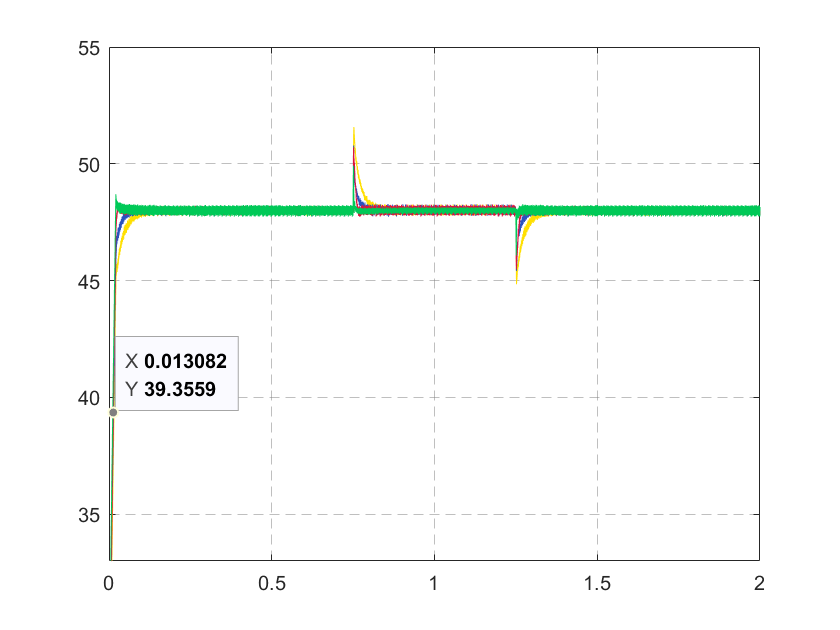

xa = DCvoltage_PI(1:4000000,1);
ya = DCvoltage_PI(1:4000000,2);
xb = DCvoltage_adp(1:4000000,1);
yb = DCvoltage_adp(1:4000000,2);
xc = DCvoltage_smc(1:4000000,1);
yc = DCvoltage_smc(1:4000000,2);
xd = DCvoltage_FbL(1:4000000,1);
yd = DCvoltage_FbL(1:4000000,2);
figure()
%蓝[42,82,190]红[220,20,60],紫[138,43,226]绿[0,201,87]黄[255,223,0]
plot(xa,ya,"color",[255/255 223/255 0/255])
hold on
plot(xb,yb,"color",[42/255 82/255 190/255])
hold on
plot(xc,yc,"color",[220/255 20/255 60/255])
hold on
plot(xd,yd,"color",[0/255 201/255 87/255])
hold off
xlim([0,2])
ylim([35,55])
xticks(0:0.5:2)
yticks(35:5:55)
grid on
ax = gca;
ax.GridLineStyle = "--";
ax.GridColor = [0.5,0.5,0.5];
ax.GridAlpha = 0.5;

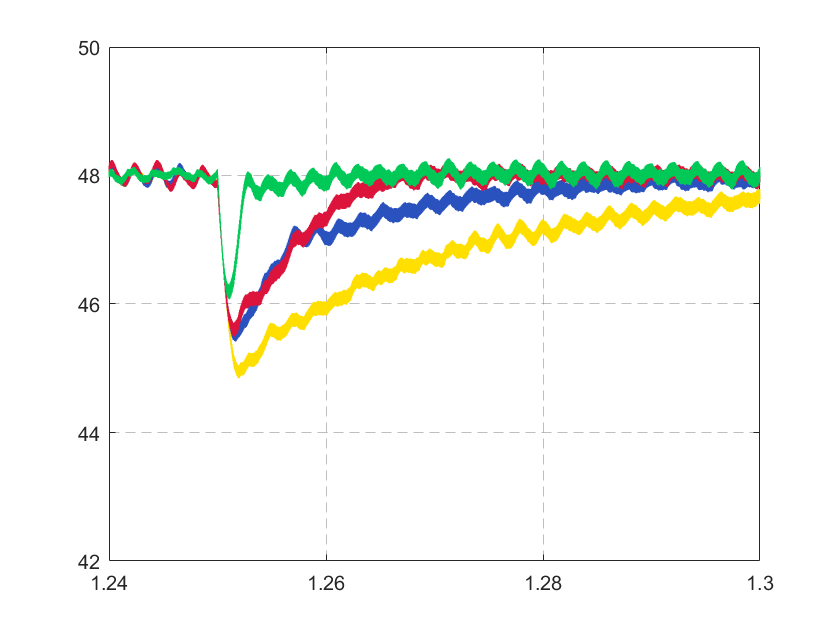

plot(xa,ya,"color",[255/255 223/255 0/255])
hold on
plot(xb,yb,"color",[42/255 82/255 190/255])
hold on
plot(xc,yc,"color",[220/255 20/255 60/255])
hold on
plot(xd,yd,"color",[0/255 201/255 87/255])
hold off
xlim([1.24,1.3])
ylim([42,50])
xticks(1.24:0.02:1.3)
yticks(42:2:50)
grid on
ax = gca;
ax.GridLineStyle = "--";
ax.GridColor = [0.5,0.5,0.5];
ax.GridAlpha = 0.5;